% script for analyzing twin-grain boundary intersection
%
% chenzhe, 2019-06-24 note
% Summarize twin growth rate as a function of SF/strainLevel/grainDiameter
% but here rate = differential twin size / differential strain, seems very imprecise  
% So this does not seem to be a good summary.

clear;
addChenFunction;

% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor','strainPauses');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\20190222_1246_twin_at_boundary_result.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','uniqueBoundary','uniqueBoundaryList','ID','gID','gExx','gPhi1','gPhi','gPhi2','gNeighbors','gNNeighbors');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

## [data] strain data. Convert into v7.3 for partial loading

clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

## (0) load data, using SF threshold values to assign active twin system, and make maps

Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

% load previous twin_gb interaction result
load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));

## (6) Summarize, does twin growth rate depend on something:  

## (here rate = differential twin size / differential strain)

close all;
um_per_dp = 360/4096*5;
T = cell2table(cell(0,11));
T.Properties.VariableNames = {'iE', 'ID', 'ts', 'variant', 'SF', 'SF_normalized', 'SF_ind', 'gVol', 'eg', 'vol', 'rate'};

eGs = -strainPauses(1:iE_stop); % make it positive value, compressive strain
for iS = 1:length(struCell{iE_start})
    tvol = zeros(6,iE_stop);
    for iE = iE_start:iE_stop
        tvol_iE = struCell{iE}(iS).tVol(:);
        if iE>iE_start
            ind = (tvol_iE==0)&(tvol_iE<tvol(:,iE-1));
            tvol_iE(ind) = tvol(ind,iE-1);
        end
        tvol(:,iE) = tvol_iE;
    end
    tvol(tvol==0) = nan;
    
    for it = 1:6
        iE = find(tvol(it,:)>0,1,'first');
        if ~isempty(iE)
            iE = iE;
            gVol = struCell{iE}(iS).gVol;
            vol_this_twin = tvol(it,:)/gVol;    % as pct of grain size
            eg = eGs(iE);
            SF = struCell{iE}(iS).tSF(it);
            SF_nor = SF/max(struCell{iE}(iS).tSF);
            SF_ind = floor(SF/0.1);
            growthRate = (vol_this_twin(2:end) - vol_this_twin(1:end-1))./(eGs(iE_start:iE_stop)-eGs(iE_start-1:iE_stop-1));
            [~,variant]=ismember(SF,sort(struCell{iE}(iS).tSF,'descend'));
            T = [T; {iE, struCell{iE}(iS).gID, struCell{iE}(iS).tLabel(it), variant, SF, SF_nor, SF_ind, gVol, eg, vol_this_twin, growthRate}];
        end
    end
end
display(T);


## (6A) Rate vs SF, at different iE, on same plot using different color

## (6A.1) rate vs Schmid factor, overall view, just plot all data points

close all;

T = 564×11 table
    iE    ID    ts    variant      SF       SF_normalized    SF_ind       gVol        eg                                vol                                            rate               
    __    __    __    _______    _______    _____________    ______    __________    _____    _______________________________________________________    _________________________________
    3     28    22       2       0.40223       0.93692         4       1.4538e+05    0.012    NaN          NaN     0.072603      0.25629      0.48134    NaN       NaN    16.699    14.066
    3     30    19       2       0.43151       0

figure; hold on;
set(gca,'ColorOrder',parula(4));
set(gca,'fontsize',18);

ind = T.iE<5;
t = T(ind,:);
gscatter(t.SF, t.rate, t.iE);
xlabel('Schmid factor');
ylabel('rate (times grain size / strain)');
lgd = legend;
lgd.String = {'iE=2-3','iE=3-4','iE=4-5'};


## (6A.2) rate vs Schmid factor, box plot. We should keep iE the same, to compare the effect of SF.

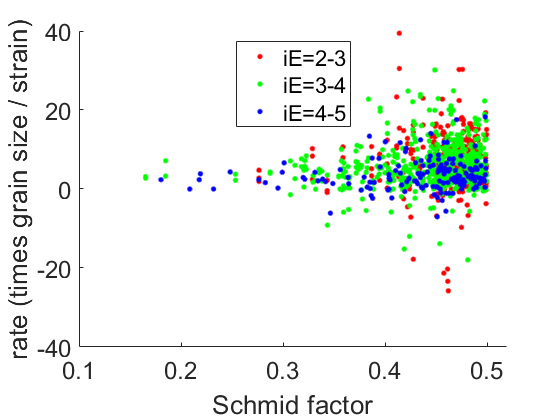

% colors = lines(4);
edges = 0.1:0.05:0.5;
for iE = 2:4
    ind = T.iE==iE;

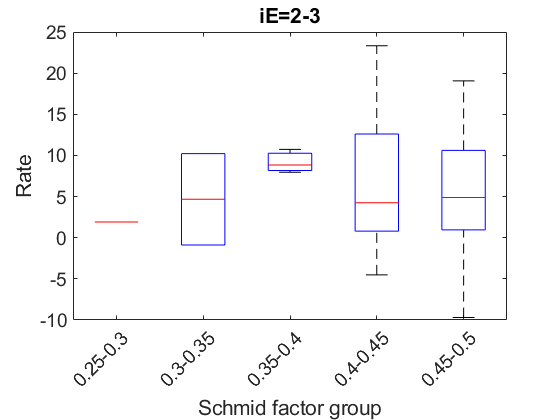

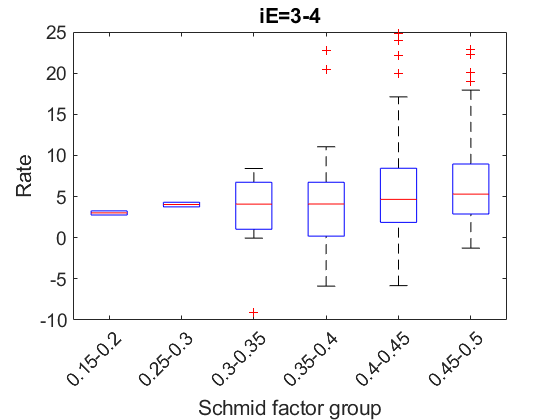

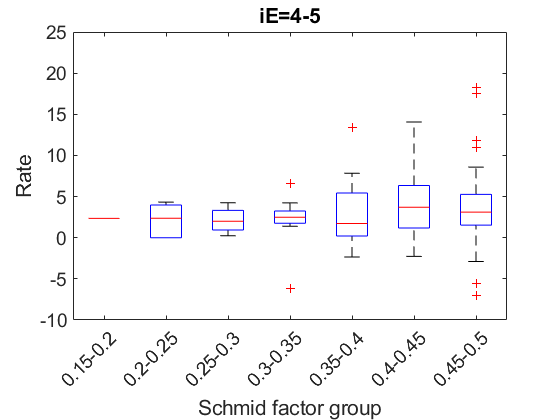

    t = T(ind,:);
    [g,~] = discretize(t.SF, edges);
    figure;
    % boxplot(t.rate(:,iE), g, 'Colors', colors(iE,:), 'positions', unique(g)+0.2*iE, 'width', 0.1);
    boxplot(t.rate(:,iE), g);
    set(gca,'fontsize',14,'ylim',[-10 25]);
    xlabel('Schmid factor group');
    ylabel('Rate');
    title(['iE=',num2str(iE),'-',num2str(iE+1)]);
    str = get(gca,'XTickLabel');
    str = replace(str,{'1','2','3','4','5','6','7','8'},{'0.1-0.15','0.15-0.2','0.2-0.25','0.25-0.3','0.3-0.35','0.35-0.4','0.4-0.45','0.45-0.5'});
    set(gca,'XTickLabel',str,'xTickLabelRotation',45);
end



## (6B.1) To study the effect of global strain, maybe we need to compare for those within similar SF range

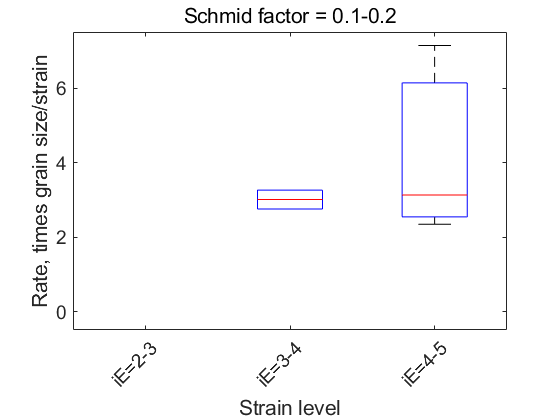

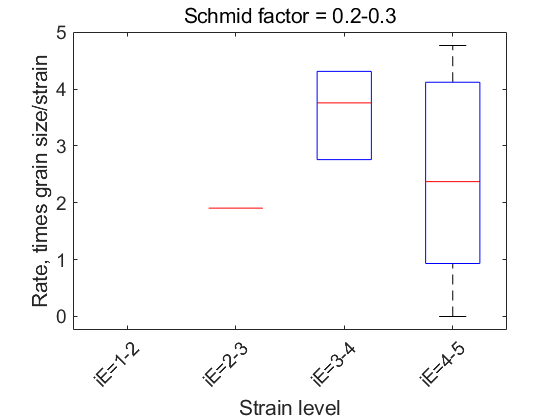

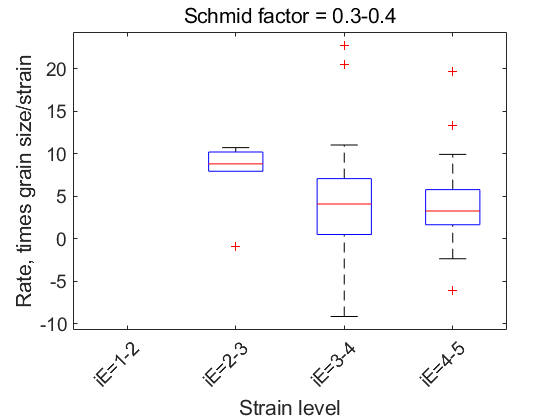

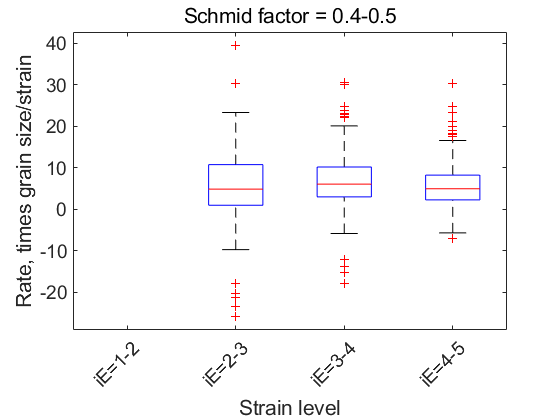

E = 0.1:0.1:0.5;    % SF edges
for ii = 1:4
    ind = (T.SF>E(ii)) & (T.SF<E(ii+1));
    t = T(ind,:);
    
    figure;
    boxplot(t.rate(:,t.iE-1), t.iE);
    xlabel('Strain level');
    ylabel('Rate, times grain size/strain');
    title(['Schmid factor = ',num2str(E(ii)),'-',num2str(E(ii+1))],'fontweight','normal');
    str = get(gca,'XTickLabel');
    str = replace(str,{'2','3','4','5'},{'iE=1-2','iE=2-3','iE=3-4','iE=4-5'});
    set(gca,'XTickLabel',str,'xTickLabelRotation',45,'fontsize',14);
    %     set(gca,'ylim',[-0.0002, 0.0005]);
end

## (6B.2) Set different y-axis limit to enlarge

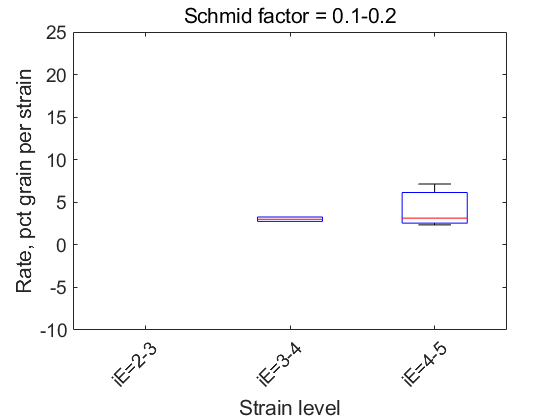

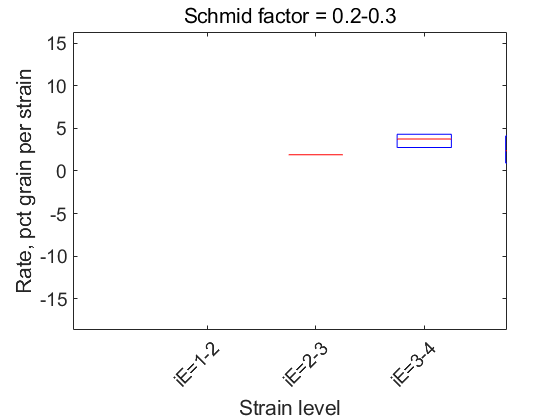

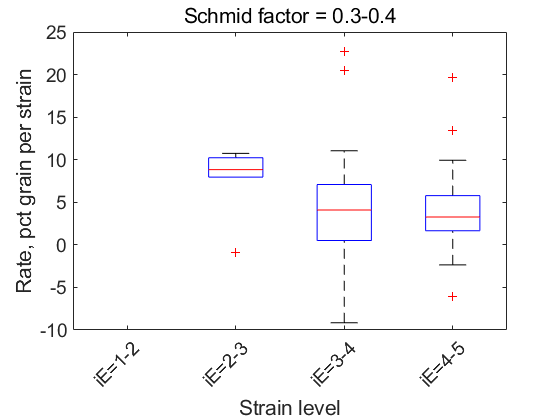

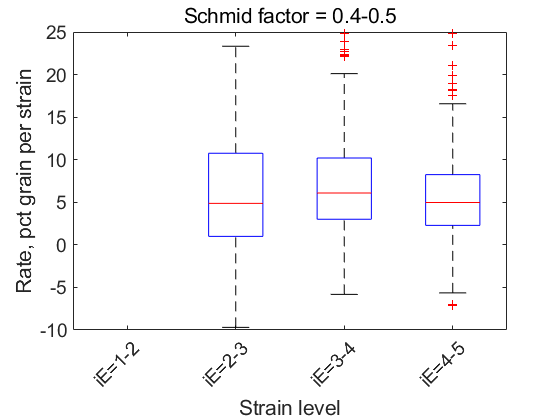

E = 0.1:0.1:0.5;    % SF edges
for ii = 1:4
    ind = (T.SF>E(ii)) & (T.SF<E(ii+1));
    t = T(ind,:);
    
    figure;
    boxplot(t.rate(:,t.iE-1), t.iE);
    xlabel('Strain level');
    ylabel('Rate, pct grain per strain');
    title(['Schmid factor = ',num2str(E(ii)),'-',num2str(E(ii+1))],'fontweight','normal');
    str = get(gca,'XTickLabel');
    str = replace(str,{'2','3','4','5'},{'iE=1-2','iE=2-3','iE=3-4','iE=4-5'});
    set(gca,'XTickLabel',str,'xTickLabelRotation',45,'fontsize',14);
    set(gca,'ylim',[-10 25]);
end

## (6C) effect of grain diameter,  but devide data into different plots by {SF, iE}.  Dont know if its good to study like this.

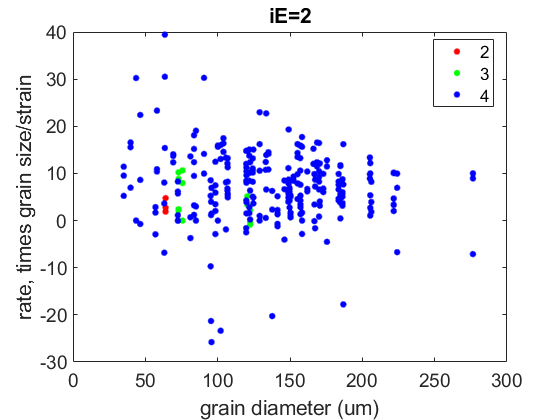

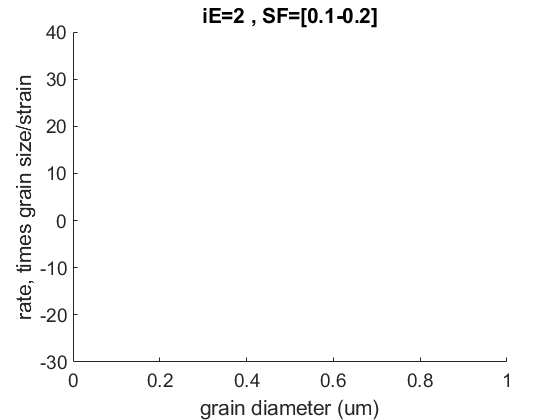

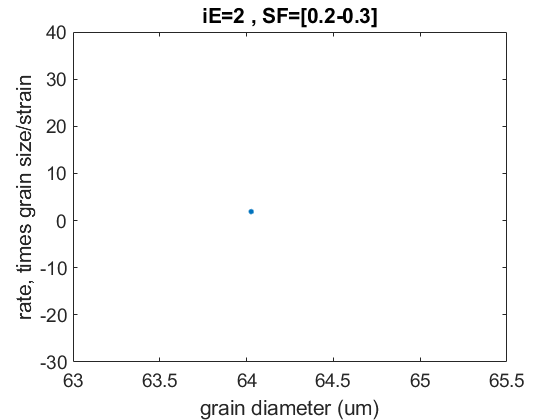

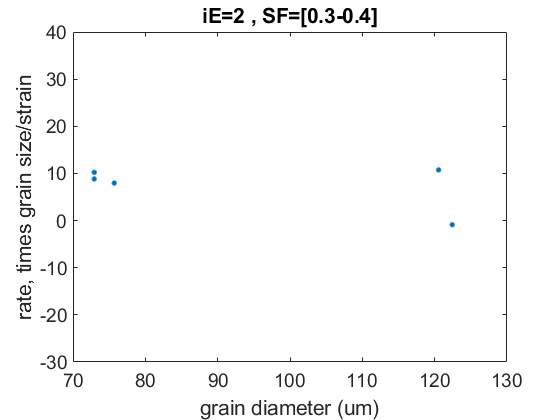

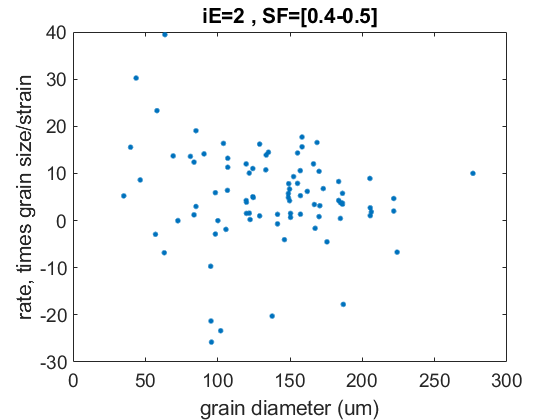

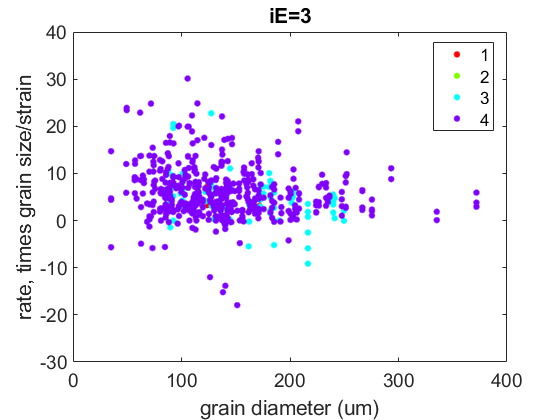

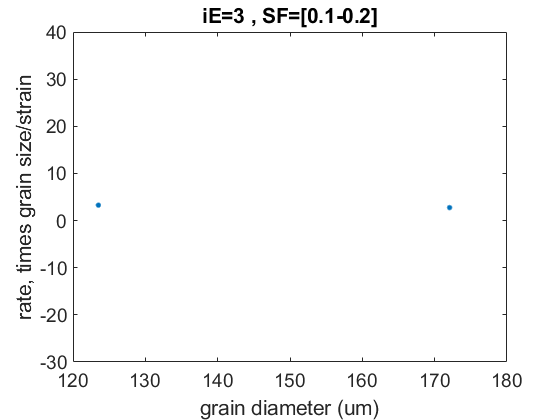

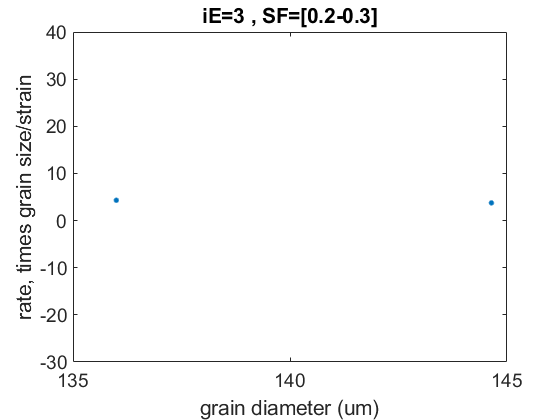

E = 0.1:0.1:0.5;    % SF edges

for iE = 2:4
    ind = T.iE==iE;
    t = T(ind,:);
    figure;
    gscatter( um_per_dp * sqrt(t.gVol * 4 / pi), t.rate, t.SF_ind);     % grain diameter
    set(gca,'ylim',[-30,40],'fontsize',14);
    xlabel('grain diameter (um)');
    ylabel('rate, times grain size/strain');
    title(['iE=',num2str(iE)]);
    for iInd = 1:4
        ind = (T.iE==iE) & (T.SF_ind == iInd);
        t = T(ind,:);
        figure;
        plot(um_per_dp * sqrt(t.gVol * 4 / pi), t.rate(:,iE), '.', 'markersize',12);
        set(gca,'ylim',[-30,40],'fontsize',14);
        xlabel('grain diameter (um)');
        ylabel('rate, times grain size/strain');
        title(['iE=',num2str(iE),' , SF=[',num2str(iInd*0.1),'-',num2str(iInd*0.1+0.1),']']);
    end
end